# **Planificación de trayectorias mediante interpolación utilizando puntos de paso**

La planificación de la trayectoria es un subconjunto del problema general que es la navegación o la planificación del movimiento. La jerarquía típica de la planificación del movimiento es la siguiente

- Planificación de tareas - Diseñar un conjunto de objetivos de alto nivel, como "ir a recoger el objeto que tiene delante".

- Planificación del 'camino' - Generación de una trayectoria factible desde un punto de partida hasta un punto de destino. Una trayectoria suele consistir en un conjunto de puntos de paso conectados.

- **Planificación de la trayectoria** - Generación de un programa de tiempo sobre cómo seguir una trayectoria dadas las restricciones como la posición, la velocidad y la aceleración.

- Seguimiento de la trayectoria - Una vez planificada la trayectoria completa, es necesario que haya un sistema de control que pueda ejecutar la trayectoria de forma suficientemente precisa.

La mayor pregunta suele ser "¿cuál es la diferencia entre la planificación de la trayectoria y la planificación del camino?". Si hay que sacar algo en claro: una trayectoria es una descripción de cómo seguir un camino en el tiempo. 

- Camino (Path): conjunto de puntos que unen el punto de inicio y de fin (únicamente posiciones)

- Trajectory: movimiento a seguir, incluyendo información temporal (posición, velocidad y aceleración).

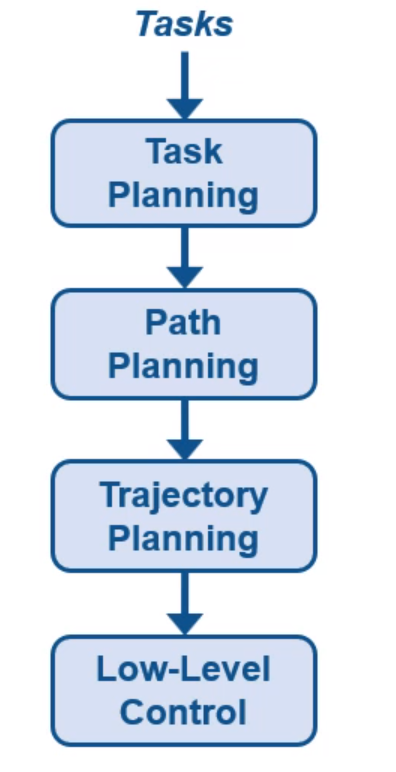

**¿Cómo planificar una trayectoria?**

En este ejemplo, ya se dispone del camino (un conjunto de puntos intermedios) de nuestro planificador de tareas, y queremos generar una trayectoria para que un manipulador siga estos waypoints a lo largo del tiempo.  Hay dos maneras de generar una trayectoria:

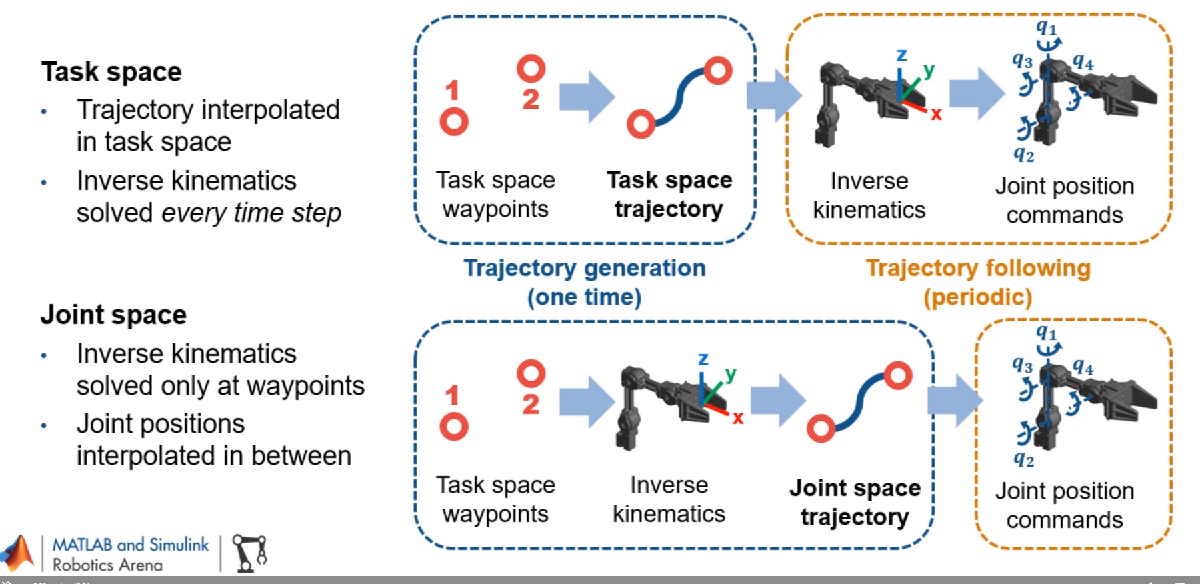

**Trayectorias en el espacio cartesiano (TASK-SPACE)**

- Se utiliza para seguir una trayectoria en el espacio determinada, por lo que la visualización del camino generado es directa y permite evitar obsctáculos conocidos.

- Requiere cinemática inversa (computacionalmente más costoso)

**Trayectorias en el espacio articular (JOINT-SPACE)**

- Utiliza directamente cada una de las articulaciones del robot qi (t)

- El movimiento en el espacio no es predecible (no se sigue una trayectoria en el espacio determinada), por lo que de manera directa no se puede visualizar el camino generado y se pueden evitar obstáculos conocidos.

- No requiere cinemática inversa en cada punto (menos costo computacional)

Ventajas e inconvenientes

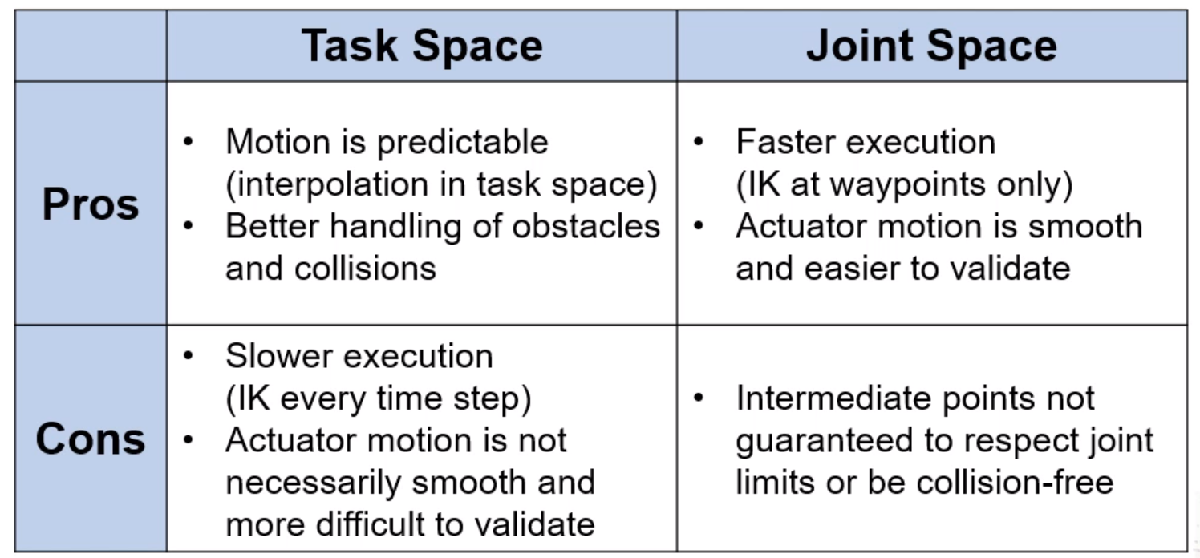

Referencia: [https://es.mathworks.com/videos/trajectory-planning-for-robot-manipulators-1556705635398.html](https://es.mathworks.com/videos/trajectory-planning-for-robot-manipulators-1556705635398.html)

## Cargar el robot

clc;
clear;
close all;
IRB120=loadrobot("abbIrb120",'Gravity',[0 0 -9.81],"DataFormat","column");
endEffector = 'tool0';
q0 = homeConfiguration (IRB120);
nJoint = numel (q0);

## Especificaciones del camino (puntos de paso)

Especificamos dos puntos de paso (punto inicial y punto final). A partir de estos dos puntos definimos la pose del end-effector del robot tomando una orientación fija.

%Puntos de paso
waypoints = [0.4550    0.1550; 
            0.0010    0.4010;   
            0.3340    0.6340];
%Definimos la pose del robot a partir de los dos puntos
fixOrienation = [pi/2    0   pi/2];
pose0 = trvec2tform(waypoints(:,1)') * eul2tform (fixOrienation);
poseF = trvec2tform(waypoints(:,2)') * eul2tform (fixOrienation);

## Especificacoines temporales de la trayecotria

Especificamos el tiempo de inicio y fin de la trayecotría, así como el tiempo de muestreo de la trayectoria.

tIni = 0;
tFin = 1;
tSample = 0.1;
tInterval = [tIni tFin];         %time interval
tvec = tIni:tSample:tFin;           %time sample
nTraj = length (tvec);     


## Generación de la trayecotria en el espacio cartesiano (TASK-SPACE)

A partir de la pose de inicio y final, definimos una trayecotria en el espacio. Para ello, utilizamos uan interpolación lineal. Una vez calculado todos los puntos de paso de la trayecotria, aplicamos la cinemática inversa para todos los puntos de paso.

tic     %calculo del tiempo de computación

%Calculamos los puntos intermedios desde el punto inicial al punto final
%mediante interpolación lineal
[tfInterp, v1, a1] = transformtraj(pose0,poseF,tInterval,tvec);

%Aplicamos la cinemática inversa para todos los puntos de paso
ik = inverseKinematics('RigidBodyTree',IRB120);
weights = [1 1 1 1 1 1]';
ikInitGuess = q0;
joints_TS = zeros (nJoint, nTraj); 
for i = 1:nTraj
    qSol = ik(endEffector, tfInterp(:,:,i),weights,ikInitGuess);
    joints_TS(:,i) = qSol';
    ikInitGuess = qSol;
end

toc

Elapsed time is 0.885360 seconds.


## Generación de la trayecotria en el espacio articular (JOINT-SPACE)

Conocido la pose inicial y final del robot, calculamos su configuración articular inicial y final con la cinemática inversa.  Calculamos la trayectoria del robot utilizando una interpolación (por ejemplo, cúbica) entre la configuración inicial y final

tic

%Calculamos la configuración inicial y final del robot con la cinemática
%inversa
qSol0 = ik(endEffector, pose0,weights,ikInitGuess);
qSolF = ik(endEffector, poseF,weights,q0);

%Calculamos la trayectoria como interpolacion cúbica entre la configuración
%inicial y final
[joints_JS, djoints_JS, ddjoints_JS, ppC] = cubicpolytraj([qSol0 qSolF], tInterval, tvec);

toc

Elapsed time is 0.235033 seconds.


## **VISUALIZACIÓN DE LAS TRAYECTORIAS EN EL ESPACIO**

Visualizamos la trayectoria que sigue el robot

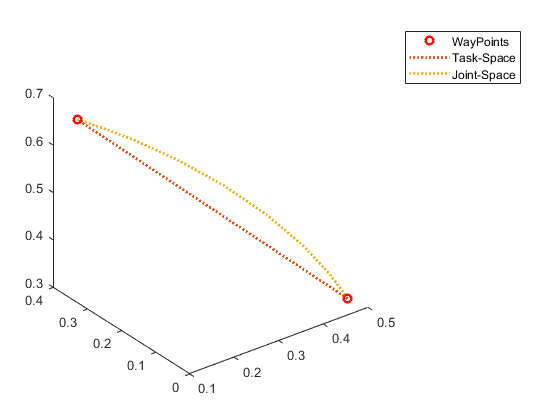

traj_TS = tform2trvec(tfInterp); 


traj_JS = zeros (nTraj,3);
for i = 1:nTraj
    traj_JS(i,:)= tform2trvec(getTransform(IRB120, joints_JS(:,i), endEffector))';
end

plot3 (waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
hold all
plot3 (traj_TS (:,1), traj_TS (:,2), traj_TS (:,3),':','LineWidth',2);
plot3 (traj_JS (:,1), traj_JS (:,2), traj_JS (:,3),':','LineWidth',2);
legend ('WayPoints','Task-Space', 'Joint-Space');

VIsualización la trayectoria seguida por el robot

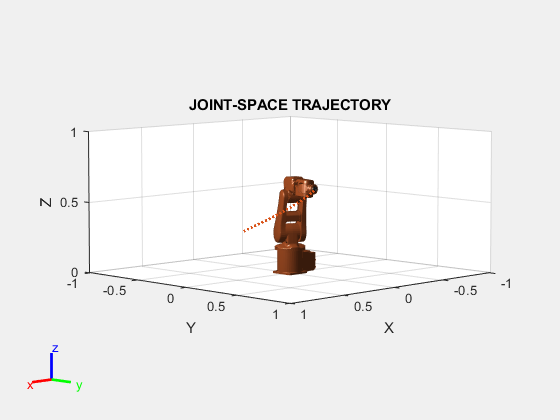

figure
set(gcf,'Visible','on')
show(IRB120,q0,'Frames','off','PreservePlot',false);
hold all
axis ([-1 1 -1 1 0 1])

a = plot3 (traj_TS (:,1), traj_TS (:,2), traj_TS (:,3),':','LineWidth',2);
for i = 1:nTraj
    show(IRB120, joints_TS(:,i),'Frames','off','PreservePlot',false);
    title ('TASK-SPACE TRAJECTORY')
    pause(0.05);
end

delete (a);
plot3 (traj_JS (:,1), traj_JS (:,2), traj_JS (:,3),':','LineWidth',2);
for i = 1:nTraj
    show(IRB120, joints_JS(:,i),'Frames','off','PreservePlot',false);
     title ('JOINT-SPACE TRAJECTORY')
    pause(0.05);
end

## VISUALIZACIÓN DE LA CONFIGURACIÓN ARTICULAR DEL ROBOT

Dibujamos las configuraciones articulares del robot.

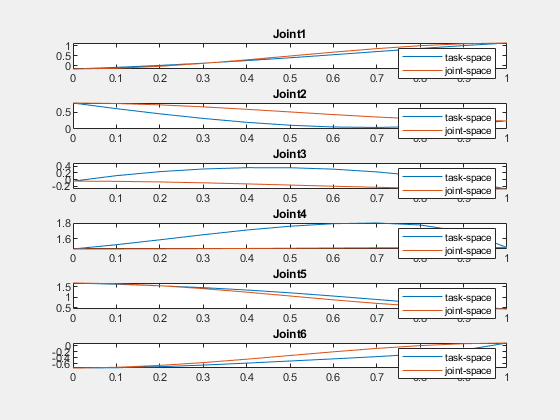

for i=1:nJoint
    subplot (nJoint,1, i)
    plot (tvec, joints_TS (i,:));
    hold on
    plot (tvec, joints_JS (i,:));
    legend ('task-space', 'joint-space');
    title (['Joint' num2str(i)]);
end

Si nos fijamos en la configuración articular de la articulación 2 del robot, opdemos observar que la trayecotria seguida en el espacio articular es más suave (menor pendiente, menos cambios) que en espacio cartesiano.

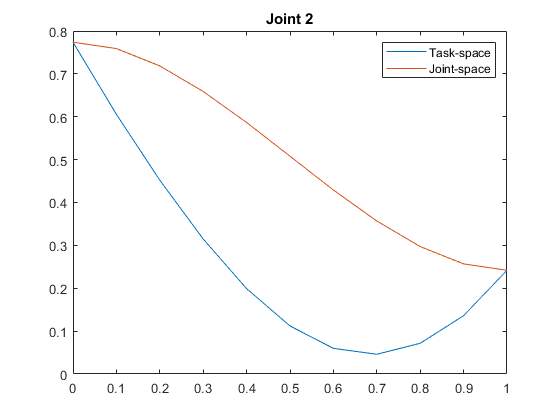

figure
plot (tvec, joints_TS (2,:));
hold on
plot (tvec, joints_JS (2,:));
legend ('Task-space', 'Joint-space');
title ('Joint 2');